# Inventory System Simulator

## Setup

#### Parameters

These are the initial parameters for the question.

%rng(123);           % Using a seed to get the same result every time.
s = 20; S = 100;    % Lower and upper bounds for the inventory level.
time_start = 0; time_stop = 100; time_infinity = 10^8; 
a = 0; b = 3;       % Min and max for order_amount amount
cost_holding = 25;

#### Part a)

We run the simulation once with the initial parameters and s=20, 

total_cost = single_run(s, S, time_start, time_stop, time_infinity, a, b, cost_holding);
fprintf('Total cost (s=20) = %.4e\n', total_cost)

Total cost (s=20) = 1.5316e+06


From this we see that the total cost for this run was $1.3846e+06

#### Part b)

For this part we create a Monte Carlo Simulation for different s values. 

First we initialise matrices to hold the outputs for each s.

N = 100; % No. of Monte Carlo runs
totals = zeros(8,1);
s_vals = zeros(8,1);

The outer loop is cycling through each s value. We initialise the s value and the total costs.

for i=1:8
    s = 5*i;
    sum_totals = 0;
    

This inner loop runs N iterations on the current s value. 

    for n=1:N
        run_cost = single_run(s, S, time_start, time_stop, time_infinity, a, b, cost_holding);
        sum_totals = sum_totals + run_cost;
    end
    % Finding the average run cost for s value and adding it to the matrices.
    avg_total = sum_totals / N;
    
    s_vals(i) = s;
    totals(i) = avg_total;
    fprintf('Total cost (s=%i) = %.4e\n', s, avg_total)
end

Total cost (s=5) = 1.5029e+06
Total cost (s=10) = 1.5025e+06
Total cost (s=15) = 1.5006e+06
Total cost (s=20) = 1.4989e+06
Total cost (s=25) = 1.5011e+06
Total cost (s=30) = 1.4962e+06
Total cost (s=35) = 1.5041e+06
Total cost (s=40) = 1.5010e+06


Finally, we plot the data

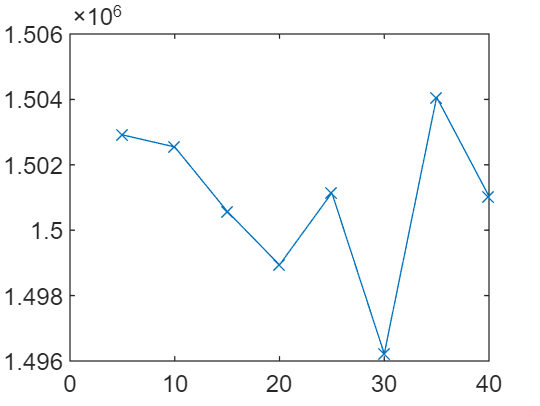

plot(s_vals, totals, '-x', 'MarkerIndices', 1:8)

#### Part c)

For this part we reset the s value, and run a Monte Carlo simulation on various S values.

We start by setting the number of iterations per S value and matrices to hold the outputs.

N = 100; % No. of Monte Carlo runs
s = 20; 
totals = zeros(9,1);
S_vals = zeros(9,1);

We then iterate through each S value

for i=1:9
    S = i*5 + 75;
    
    % Finding holding cost based on S
    if S<90
        cost_holding = 27;
    elseif S<110 && S>=90
        cost_holding = 25;
    elseif S>110
        cost_holding = 22;
    end

For each S we run a Monte Carlo simulation with N iterations and store its average costs

    sum_totals = 0;
    for n=1:N
        run_cost = single_run(s, S, time_start, time_stop, time_infinity, a, b, cost_holding);
        sum_totals = sum_totals + run_cost;
    end
    
    % Finding and storing averages.
    avg_total = sum_totals / N;
    s_vals(i) = S;
    totals(i) = avg_total;
    fprintf('Total cost (S=%i) = %.4e\n', S, totals(i))
end

Total cost (S=80) = 1.5109e+06
Total cost (S=85) = 1.5086e+06
Total cost (S=90) = 1.5050e+06
Total cost (S=95) = 1.5028e+06
Total cost (S=100) = 1.4983e+06
Total cost (S=105) = 1.4995e+06
Total cost (S=110) = 1.4930e+06
Total cost (S=115) = 1.4894e+06
Total cost (S=120) = 1.4871e+06


Plotting the data

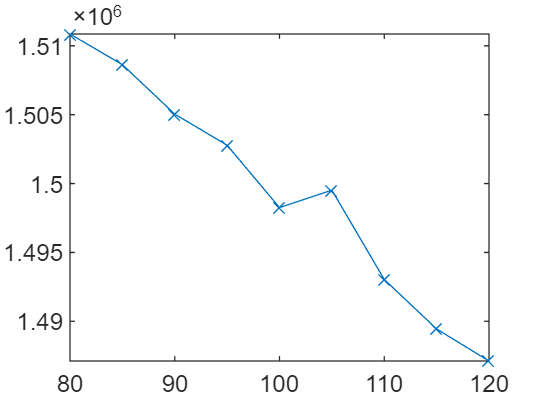

plot(s_vals, totals, '-x', 'MarkerIndices', 1:9)

## Single Run for Simple Inventory 

This function simulates a simple inventory system with the given parameters.

The first section sets the initial paramters for the system

function total_cost = single_run(s, S, time_start, time_stop, time_infinity, a, b, cost_holding)
inventory = S; order_amount = 0;
sum_setup = 0; sum_holding = 0; sum_shortage = 0; sum_order = 0; 
sum_demand = 0; sum_lag=0;
time_current = time_start;
time_demand  = Exponential(1/120);         % Schedule the first demand
time_review  = time_current + 1.0;      % Schedule the first review
order_arrival_time  = time_infinity;

#### Main Loop

Runs the main loop while the cureent time is smaller than the stop time.

Starts by finding the next time unit. Then updates the totals for units of holding and units of shortage.

while time_current < time_stop
  time_next = min([time_demand,time_review,order_arrival_time]);
  if inventory > 0  
      sum_holding = sum_holding + (time_next-time_current)*inventory;
  else
      sum_shortage = sum_shortage - (time_next-time_current)*inventory;
  end
  time_current = time_next;

We now check what needs attention in this unit of time. 

Note: Initially the simulation used an "IfElse" block for all the separate events, but I changed this to be in separate "If" statements. If the current time was both a demand point and a review time, it would only process the demand, but now it will process both the demand and the review.

First we check if we have a demand for the current time, and update the sums and inventory level.

  if time_current == time_demand
      amount = UniformInt(a,b);                         % Amount demanded
      sum_demand = sum_demand + amount;
      inventory = inventory - amount;                   % Inventory level reduced by amount
      time_demand = time_demand + Exponential(1/120);   % Sets time for next demand
  end 

Next, we check if we need to "review" the inventory level, if we do we check if we need to order more stock and update the totals.

  if time_current == time_review  
      if inventory < s                                      % Checks if inventory is low
         order_amount = S - inventory;                      % Sets order amount for max inventory      
         sum_setup = sum_setup + 1;                         % Adding to setup counts
         sum_order = sum_order + order_amount;
         lag_time = Uniform(0.0,1.0); 
         sum_lag = sum_lag  + lag_time;
         order_arrival_time   = time_current + lag_time;    % Setting next order arrival time
       end
       time_review = time_current + 1;
  end

Finally, we check if a new order has arrived, if so update the inventory to reflect this.

  if  time_current == order_arrival_time
       inventory = inventory + order_amount;
       order_amount = 0;
       order_arrival_time = time_infinity;
  end
end  

We reset the inventory after the time period.

 if inventory < S
      order_amount = S - inventory;
      sum_setup = sum_setup+1;
      sum_order = sum_order + order_amount;
      inventory = inventory + order_amount; %#ok
 end


#### Calculating outputs

Calculate the average number of demand, order, setup, holding and shortage per unit time.

avg_demand = sum_demand/time_stop;
avg_order = sum_order/time_stop; %#ok
avg_setup = sum_setup/time_stop;
avg_holding = sum_holding/time_stop;
avg_shortage = sum_shortage/time_stop;

% fprintf('##Averages##')
% fprintf('Demand = %.4e\n', avg_demand)
% fprintf('Order = %.4e\n', avg_order)
% fprintf('Set-up = %.4e\n', avg_setup)
% fprintf('Holding = %.4e\n', avg_holding)
% fprintf('Shortage = %.4e\n', avg_shortage)

We then calculate the average costs, and has the option to print the costs to the console

cost_demand = 8000;
cost_setup = 1000;
cost_shortage = 700;

avg_cost_demand = cost_demand * avg_demand;
avg_cost_setup = cost_setup * avg_setup;
avg_cost_holding = cost_holding * avg_holding;
avg_cost_shortage = cost_shortage * avg_shortage;
total_cost = avg_cost_demand + avg_cost_setup + avg_cost_holding + avg_cost_shortage;

% fprintf('##Average Costs##')
% fprintf('Demand = %.4e\n', avg_cost_demand)
% fprintf('Set-up = %.4e\n', avg_cost_setup)
% fprintf('Holding = %.4e\n', avg_cost_holding)
% fprintf('Shortage = %.4e\n', avg_cost_shortage)
% fprintf('Total = %.4e\n', total_cost)
end
% End of function

## Define functions

Functions finding random numbers based on a distribution

function dnum = UniformInt(a,b)
    dnum = floor(rand() * (b+1-a)) + a;
end 
function s = Exponential(mu)
    s = -mu*log(1.0 - rand());
end 
function s = Uniform(a,b)
    s = a +(b-a)*rand();
end 
function s = Geometric(p) %#ok
    s = floor( log(1.0 - rand() )/log(p) );
end